# Run and plot Solar Balloon prediciton

clearvars

## Compilr and Run C++ code


command = 'dir';
[status1,cmdout1] = system(command);
command = 'g++ -O2 -Wall -Wno-unused-result sphere_balloon.cpp std_atm.cpp rad_flux.cpp main.cpp -o run';
[status2,cmdout2] = system(command);
command = 'run.exe';
[status3,cmdout3] = system(command);


## Pares Prediction Data


opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["time", "elevation", "internal_T", "dT", "velocity"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Import the data
SBprediction = readtable(".\out.dat", opts)

SBprediction = 827×5 table
      time      elevation    internal_T       dT        velocity
    ________    _________    __________    _________    ________

    -0.71706      132.6        287.29       -6.3e-05       0    
    -0.68928      132.6        287.24      -0.044515       0    
    -0.66151      132.6        287.21      -0.082707       0    
    -0.63373      132.6        287.17       -0.11511       0    
    -0.60595      132.6        287.15       -0.14271       0    
    -0.57817      132.6        287.12       -0.16632       0    
    -0.55039      132.6         287.1       -0.18659       0    
    -0.52262      132.6        287.08       -0.20406       0    
    -0.49484      132.6        287.07       -0.21918       0    
    -0.46706      132.6        287.06        -0.2323       0    
    -0.43928      132.

## Clear temporary variables

clear opts


## plot

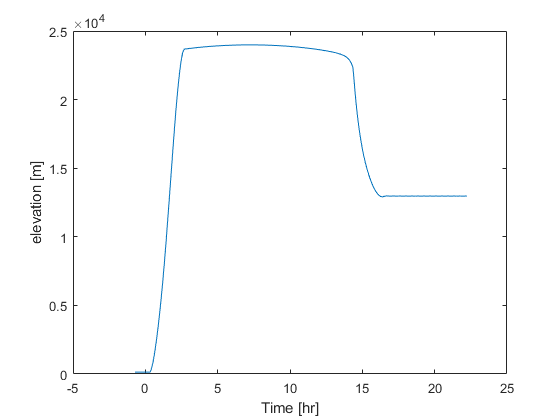

figure(2)
plot(SBprediction.time,SBprediction.elevation)
xlabel('Time [hr]')
ylabel('elevation [m]')

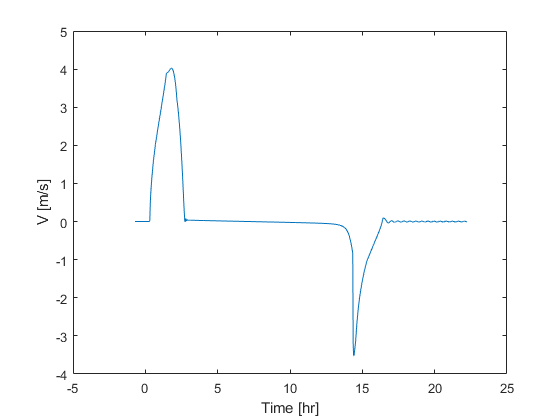


figure(3)
plot(SBprediction.time,SBprediction.velocity)
xlabel('Time [hr]')
ylabel('V [m/s]')

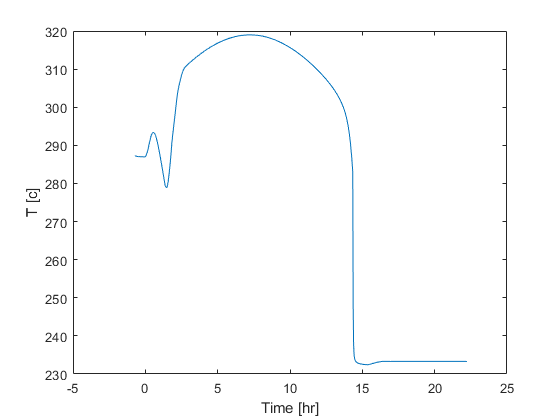


figure(4)
plot(SBprediction.time,SBprediction.internal_T)
xlabel('Time [hr]')
ylabel('T [c]')

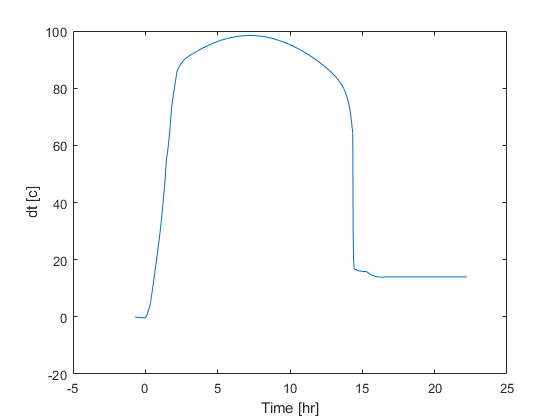


figure(5)
plot(SBprediction.time,SBprediction.dT)
xlabel('Time [hr]')
ylabel('dt [c]')